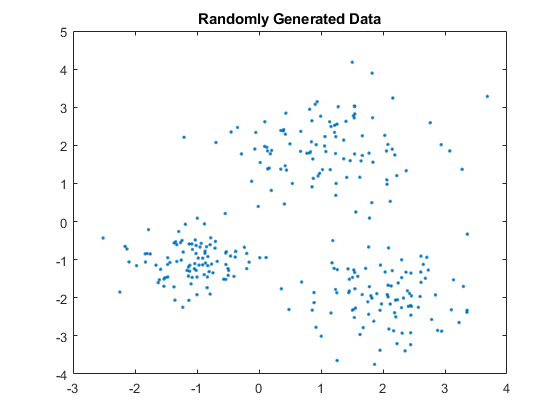

clear;
close all;
clf reset;
%argmin sum from j=1 to k of sum of i=1 to n of m(i,j) || xi - cj||^2
%Given centroids {c(j)} then m(i,j) = 1 if j = arg min of j within 1 to K
%of || xi - cj||^2. 0 otherwise.

%Given the memberships {m(i,j)}, then c(j) = sum from i=1 to n of
%[m(i,j)*x(i)] / sum of i=1 to n of [ m(i,j)]

rng default; % For reproducibility
X = [randn(100,2)*0.75+ones(100,2);
    randn(100,2)*0.5-ones(100,2)];

temp = randn(100,2)*0.75;
temp(:, 1) = temp(:, 1) + 2*ones(100, 1);
temp(:, 2) = temp(:, 2) - 2*ones(100, 1);
X(1:100, 2) = X(1:100, 2) + ones(100, 1);
X = [X; temp];


plot(X(:,1),X(:,2),'.');
title 'Randomly Generated Data';

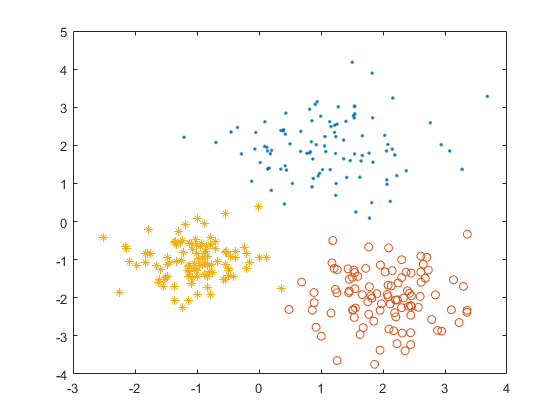


k = 3;

m = kMeans(X, k);
%Have 5 groups for plotting up to k=5 groups. Can be extended pretty
%easily. Just add more groups and plots.
g1 = X(m(:) == 1, :);
g2 = X(m(:) == 2, :);
g3 = X(m(:) == 3, :);
g4 = X(m(:) == 4, :);
g5 = X(m(:) == 5, :);

plot(g1(:,1),g1(:,2),'.');
hold on
plot(g2(:,1),g2(:,2),'o');
plot(g3(:,1),g3(:,2),'*');
plot(g4(:,1),g4(:,2),'+');
plot(g5(:,1),g5(:,2),'x');

hold off

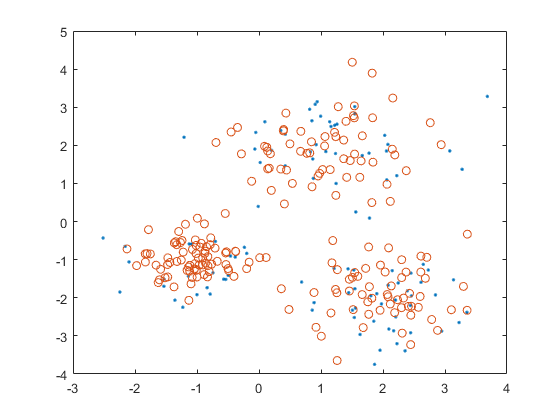


Xt = X';
[v, d] = eig(Xt'*Xt);

Ys = zeros(size(Xt, 2), k);
for i=1:k
    Ys(:, i) = v(:, i);
end

% Xr = Xt * Ys;
m = kMeans(Ys, k);
%Have 5 groups for plotting up to k=5 groups. Can be extended pretty
%easily. Just add more groups and plots.
g1 = X(m(:) == 1, :);
g2 = X(m(:) == 2, :);
g3 = X(m(:) == 3, :);
g4 = X(m(:) == 4, :);
g5 = X(m(:) == 5, :);

plot(g1(:,1),g1(:,2),'.');
hold on
plot(g2(:,1),g2(:,2),'o');

plot(g3(:,1),g3(:,2),'*');
plot(g4(:,1),g4(:,2),'+');
plot(g5(:,1),g5(:,2),'x');



function kmns = kMeans(x, k)
    n = length(x);
    r = round(1 + (n-1).*rand(k,1));
    c = ones(k, size(x, 2));
    
    %Get random starting centroids
    for i=1:k    
        c(i, :) = x(r(i), :);
    end
    %Initiate 'old' centroid values to be all 0.
    oldC = zeros(k, size(x, 2));
    
    count = 0;
    while (oldC ~= c)
        count = count + 1;
        %Store the previous centroids for termination
        oldC = c;
        %Reinitialize the groups to be empty.
        m = zeros(n, 1);
        %iterate through all the data
        for i=1:n
            %initialize a distance matrix of zeros.
            dists = zeros(k, 1);
            for j=1:k
                %Get the distances for each centroid.
               dists(j) = sqrt(sum((x(i, :) - c(j, :)).^2)); 
            end
            %Get the closest centroid index and store it in the
            %corresponding spot in m.
            [M, I] = min(dists);
            m(i) = I;
        end
        %Calculate new centroids.
        for j=1:k
            temp = (m(:) == j);
            %t = size(x, 1) - size(temp, 1);
            %temp = [temp; zeros(t, 2)];
            %c(j, 1) = sum(temp .* x(:, 1)) /sum(m(:) == j);
            %c(j, 2) = sum(temp .* x(:, 2)) /sum(m(:) == j);
            c(j, :) = sum(temp .* x)./sum(m(:) == j);

        end
        checkpoint = 0;
    end
    
    kmns = m;
    
end